# IPV Assignment 3 (week 3) 

## **Q1: for Part 5 (un)sharpening: **The two (un)sharping filters (“**a-laplace(a)**” and “**2*a - gaussf(a)**”) are not the same. Can you explain the difference of them? How are they alike? 

To explain that, we need to understand what is the meaning of this two operations and how to implement them.

**Understanding 2*a - gaussf(a)**

**Gaussian Filter**

Gaussian filter was deeply explained on the assignment of last week. Its main features are:

- **High-frequency component filter: **The Gaussian filter masks the details in the image, being a good filter for noise reduction and smoothing/blurring.

- **Linear filter: **Uses a 2D Normal Distribution to create its convolution matrix.

- **Sigma parameter: **Determines the strength of the filter, usually the matrix convolution size is calculed using this value. As sigma increase, the output get molt blurred.

**Multiplication by a scalar**

The first operation that we are doing here is `2*a`. When we multiplicate an Image using an scalar, we are changing the relative intensity of the pixels. The relative intensity is directly related to the contrast, because we use the differences of intensity between some areas of the image to distinguish different intensity areas as different objects in the picture.

We prepare the environment:

clear
addpath('/lib/dip/common/dipimage');  % Adds path to diplib
dip_initialise;  % Initilialize libraries


DIPlib 2.9 (Oct 16 2017 - Release [on Linuxa64 (with OpenMP)])
    Scientific Image Analysis Library
    Quantitative Imaging Group, Delft University of Technology 1995-2017
    info@diplib.org


dipIO 2.9 (Oct 16 2017 - Release)
    File I/O library for DIPlib
    Quantitative Imaging Group, Delft University of Technology 1999-2017
    info@diplib.org



dipsetpref('imagefilepath','/home/amt/IPV/');  % Optional: sets default image saving/loading folder

For example, in the image cermet we can see that the difference between the maximum and minimum intensity in the picture is 30:

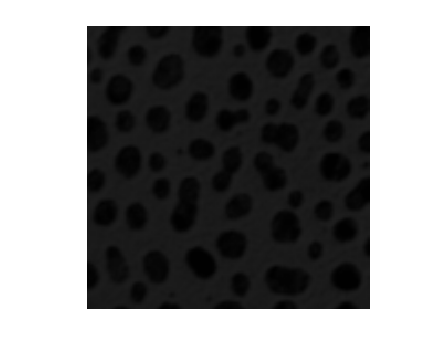

a = readim('cermet.tif');
imshow(dip_array(a));

disp(max(max(dip_array(a))) - min(min(dip_array(a))))

   30



In this case we are losing a lot of possible contrast since we are using 8 bits for intensity encoding (allowing a range up to 2^8 different intensities) but we are just using a range of 30 values to represent it.

But if we multiply the image using an scalar the difference between the maximum and the minimum intensity in the image gets multiplied too.

disp(max(max(3*a)) - min(min(3*a)))

    90



The bigger is the intensity in a pixel, the bigger it will be in the output because of the nature of the multiplication operation. That means that light colors will get much lighter than dark colors do after applying this operation. For example, the zones of the image with small values (darker areas) will still have small values after get multiplied, but light colours with higher intensities will be easily approaching to white color. Meaning that the intensity of lighter pixels gets saturated, losing contrast between light areas and making them more uniform. That can only happen in images that are really light, so the `cermet` is not a good example. We need to multiplicate the image many times before that happens:

saturating_scalar = 2^8 / max(max(dip_array(a))) + 1  % For a uint8 image --> 2^8 max value

saturating_scalar = uint8
9

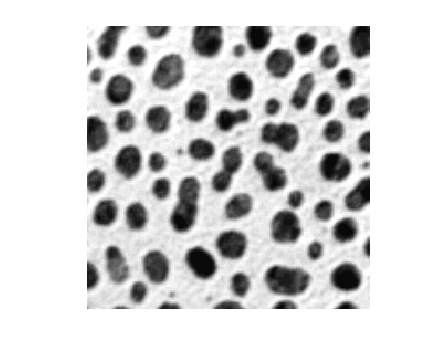

imshow(dip_array(a)* saturating_scalar);

In this case the contrast between objects and the background is bigger.

We can see also how the histogram of the image evolves with the multiplication by an scalar, making the points on it more disperse.

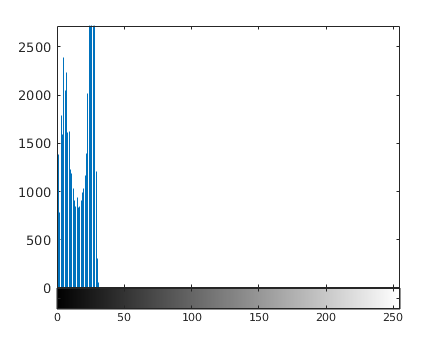

imhist(dip_array(a));

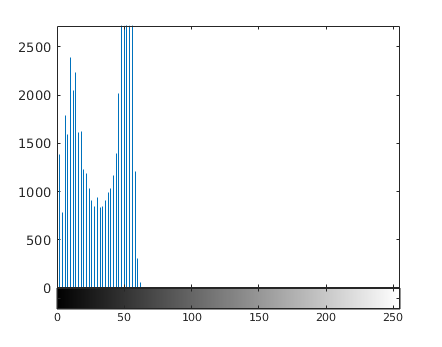

imhist(dip_array(a) * 2);

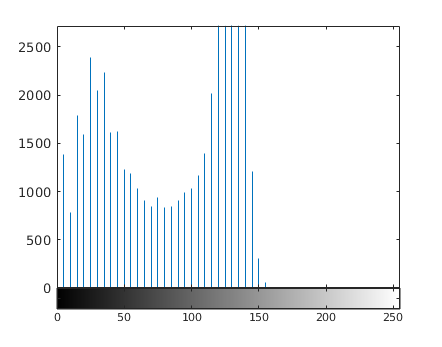

imhist(dip_array(a) * 5);

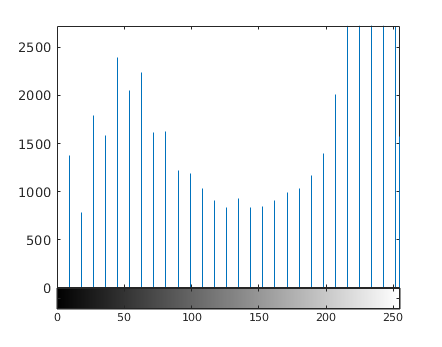

imhist(dip_array(a) * saturating_scalar);

Finally, to compare, the histogram of the output from the histogram equalization function.

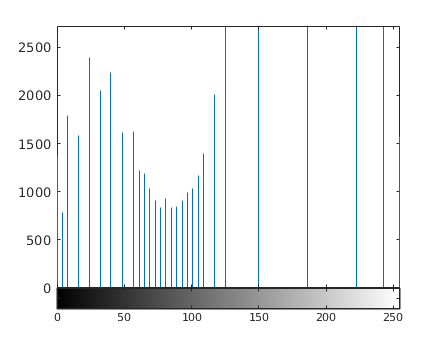

imhist(histeq(dip_array(a)));

You can notice that the distribution of the intensities is similar between the output of `histeq `and `a * 5.`

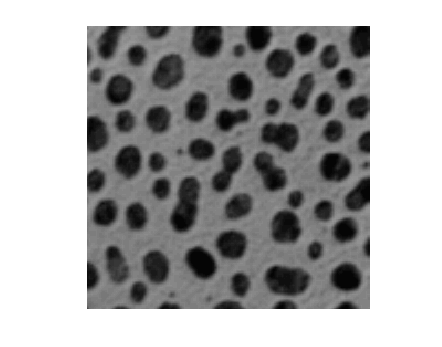

imshow(dip_array(a) * 5);

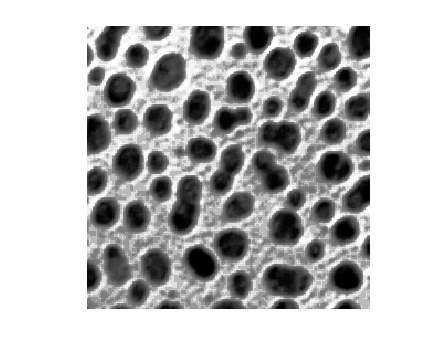

imshow(histeq(dip_array(a)));

But is similar just for the darker pixels, forming the dark objects of the image.

Let's try the given operation on a lighter image with more contrast:

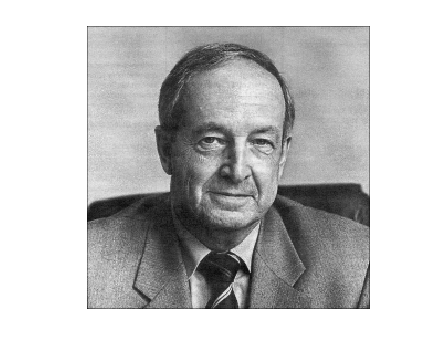

b = readim('devoogd.tif');
imshow(dip_array(b));

disp(max(max(dip_array(b))));

   243



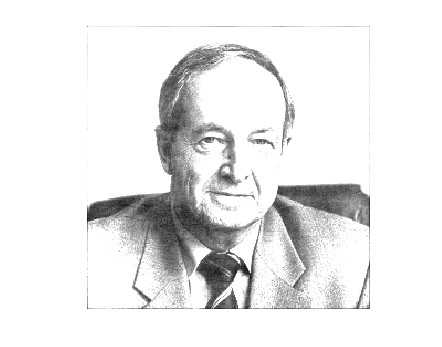

imshow(dip_array(b) * 2);

We can see how the effect of the multiplication is bigger on images with a wider range of intensities.

So, we can conclude saying that the multiplication of an scalar by an image:

- Produces an image with **a bigger difference between pixels of different intensity**. 

- The lighter areas can be saturated easily in lighter photos, **losing the contrast between the pixels forming them**.

- At the same time, **contrast between light and dark areas increase.**

**Meaning of the substraction between the multiplication and the Gaussian filtered image**

First, we need to be aware of :


$$\lim_{\sigma \to 0} \;2*a-\mathrm{gaussf}\left(a,\sigma \right)\;=a$$


So, the difference between the input image $a$ and the output of our operation depends entirely on $\sigma$.

To see the effect of the filter we are going to try different values of sigma 

for i=0:0.25:1.5
    
end

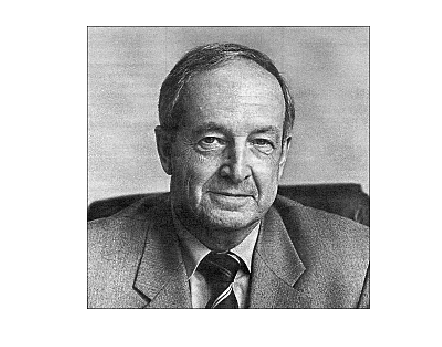

outputG_0 = uint8(dip_array(double(dip_array(b)) * 2 - gaussf(dip_array(b), 0)));

outputG_1 = uint8(dip_array(double(dip_array(b)) * 2 - gaussf(dip_array(b), 1)));

ans = logical
   1


imshow(outputG_0);

difference = 256×256 single matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0  

imshow(outputG_1);

ans = single
0

isequal(outputG_0, dip_array(b))
difference = dip_array(b - outputG_0)
sum(sum(difference))


**References**

[http://spatial-analyst.net/ILWIS/htm/ilwisapp/filters_types_gradient_or_derivative_filters_technical_information.htm](http://spatial-analyst.net/ILWIS/htm/ilwisapp/filters_types_gradient_or_derivative_filters_technical_information.htm)

[https://en.wikipedia.org/wiki/Image_derivatives](https://en.wikipedia.org/wiki/Image_derivatives)

[https://www.swarthmore.edu/NatSci/mzucker1/e27_s2016/filter-slides.pdf](https://www.swarthmore.edu/NatSci/mzucker1/e27_s2016/filter-slides.pdf)

[http://mccormickml.com/2013/02/26/image-derivative/](http://mccormickml.com/2013/02/26/image-derivative/)

[https://homepages.inf.ed.ac.uk/rbf/HIPR2/log.htm](https://homepages.inf.ed.ac.uk/rbf/HIPR2/log.htm)

- Dogra A, Bhalla P. Image Sharpening By Gaussian And Butterworth High Pass Filter. Biomed Pharmacol J 2014;7(2). Available [here](http://biomedpharmajournal.org/?p=3274).

- Wikipedia, [Partial Derivative](https://en.wikipedia.org/wiki/Partial_derivative).